clear all, close all, clc

## HW05-1

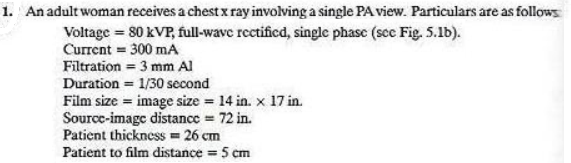

Given that

V = 80;             % voltage, full-wave, rectified single phase; kVP
I = 300;            % Current; mA
fl = 3;             % filtration, Al; mm
t = 1/30;           % duration; s
FS = 14*17;         % film size; in^2
SID = 72*2.54;      % source to image distance; cm
tp = 26;            % patient thickness; cm
PID = 5;            % patient to image distance; cm
SPD = SID -(PID + tp);  % source to patient distance; cm
SPD = SPD *0.394    % in

SPD = 59.8407

Now, from textbook, figure 5.1(b), we find that, for 3 mm-Al filtration, and at 80 KVp,  the reference exposure is-

5 mR/mA.s

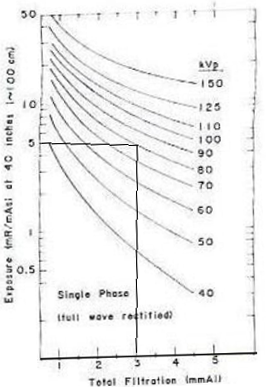

Ex_R = 5;               % reference exposure rate; mR/mA.s
Ex = 5*I*t;             % exposure; mR
Ex = Ex*1e-3            % exposure; R

Ex = 0.0500

Now, let's find the HVL for the X-Ray beam. From Table 5.1 of the textbook, we find, for the given information, the HVL is 2.62 mm-Al

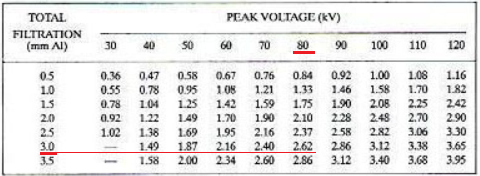

Now, let's find the doses and CDI at thyroid, bone marrow, breasts, and lungs

Given that, the X-ray was done at PA view. Now, from book Table 5.2, we have-

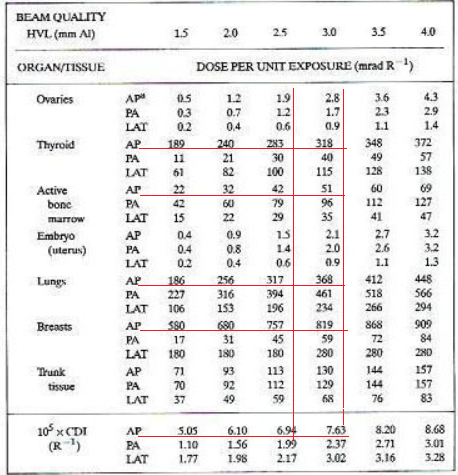

Herefrom, we find the followings-

**Thyroid**

HVL1 = 2.5;                 % HVL; mm
HVL2 = 3.0;                 % mm
HVL = 2.62;                 % HVL of interest; mm
DE_t_1 = 283;               % dose/exposure, thyroid, HVL1; mrad.R^-1
DE_t_2 = 318;               % dose/exposure, thyroid, HVL2; mrad.R^-1

  HVLs = [HVL1, HVL2];      % defining vectors
  DEs_t = [DE_t_1, DE_t_2];
DE_t = interp1(HVLs, DEs_t, HVL)    % dose/exposure, thyroid, HVL; mrad.R^-1

DE_t = 291.4000

D_t = DE_t *Ex                  % dose, thyroid; mrad

D_t = 14.5700

(Ans)

**Bone Marrow**

DE_bm_1 = 42;               % dose/exposure, b.marrow, HVL1; mrad.R^-1
DE_bm_2 = 51;               % dose/exposure, b.marrow, HVL2; mrad.R^-1
  
  DEs_bm = [DE_bm_1, DE_bm_2];    
DE_bm = interp1(HVLs, DEs_bm, HVL)     % dose/exposure, b.marrow, HVL; mrad.R^-1

DE_bm = 44.1600

D_bm = DE_bm *Ex                  % dose, b.marrow; mrad

D_bm = 2.2080

(Ans)

**Lungs**

DE_l_1 = 317;               % dose/exposure, lungs, HVL1; mrad.R^-1
DE_l_2 = 368;               % dose/exposure, lungs, HVL2; mrad.R^-1
  
  DEs_l = [DE_l_1, DE_l_2];    
DE_l = interp1(HVLs, DEs_l, HVL)     % dose/exposure, lungs, HVL; mrad.R^-1

DE_l = 329.2400

D_l = DE_l *Ex                  % dose, lungs; mrad

D_l = 16.4620

(Ans)

**Breasts**

DE_b_1 = 757;               % dose/exposure, breasts, HVL1; mrad.R^-1
DE_b_2 = 819;               % dose/exposure, breasts, HVL2; mrad.R^-1
  
  DEs_b = [DE_b_1, DE_b_2];    
DE_b = interp1(HVLs, DEs_b, HVL)     % dose/exposure, breasts, HVL; mrad.R^-1

DE_b = 771.8800

D_b = DE_b *Ex                  % dose, breasts; mrad

D_b = 38.5940

(Ans)

**CDI (Cancer Detriment Index)**

CDI_E_1 = 6.94e5;             % CDI/exposure, HVL1; R^-1
CDI_E_2 = 7.63e5;             % CDI/exposure, HVL2; R^-1
  
  CDI_Es = [CDI_E_1, CDI_E_2];    
CDI_E = interp1(HVLs, CDI_Es, HVL)     % CDI/exposure, HVL; R^-1

CDI_E = 710560

CDI = CDI_E *Ex                  % CDI*1e5

CDI = 35528

CDI = CDI/1e5                    % CDI 

CDI = 0.3553

(Ans)

## **HW05-2**

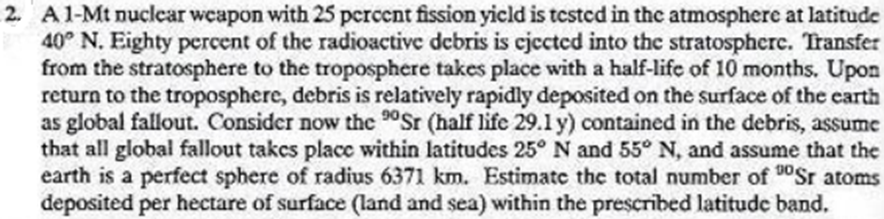

We know,

Nf = 1.45e26;           % no. of fissions in 1 MT of weapon
y_sr = 0.051;           % fission yield of Sr-90

Given that,

Wt = 1;                 % weapon mass; Mt
y_w = 0.25;             % weapon fission yield

Then, the number of fissions took place-

Nf_T = Wt *y_w *Nf      % Total fission from weapon test

Nf_T = 3.6250e+25

Given, 80% of the radioactive debris went to the startosphere. So-

ej = 0.8;               % percent of stratospheric ejection
Nf_s = Nf_T*ej          % FPs reached to stratosphere 

Nf_s = 2.9000e+25

Here it is said that, there are Sr-90 within the fission products. So, number of Sr-90 would be-

N_Sr = Nf_s*y_sr        % No. of Sr-90 ejected to stratosphere

N_Sr = 1.4790e+24

Now, these Sr-90 radioactively decays with HL = 29.1 year. Also given-

HL = 10;                % HL of transfer from stratosphere to troposphere of debris; mo
HL = 60^2*24*30         % HL; sec

HL = 2592000

Now, let's find the decay-constant of that transfer, $\lambda_t$

lam_t = log(2)/HL       % decay const. of transfer; s^-1

lam_t = 2.6742e-07

Now, assuming 99.99% percent of transfer to the troposphere, we have-

$\frac{N_d \left(T\right)}{N_{\textrm{od}} }=f=e^{-\lambda {\;}_t T}$;  $N_d \left(T\right)=$ no. of radionuclide debris remaining after time-period T

f = 0.9999;             % fraction of debris that transfer to troposphere after T
fr = 1-f;               % fraction, that remains
T = -log(fr)/lam_t     % total time of strato-tropo transfer of debris; sec

T = 3.4442e+07

Within this time period (T), the Sr-90 decays into its daughter product. Now, let's find, how much Sr-90 remains afterwards

Th_Sr = 29.1;               % Half Life, Sr-90; y
Th_Sr = Th_Sr*60^2*24*365   % Half life of Sr-90; s

Th_Sr = 917697600

lam = log(2)/Th_Sr          % decay constant, Sr-90; s^-1

lam = 7.5531e-10

We know, $N\left(T\right)=N_o \;e^{-\lambda \;T}$    $N\left(T\right)=$ no. of radioinuclides remaining after time T. So,

NT_Sr = N_Sr *exp(-lam*T)   % No. of Sr-90 reached to troposhpere(so, ground)

NT_Sr = 1.4410e+24

Now, let's measure the area where the fallout takes place. As it is shown in the picture follows-

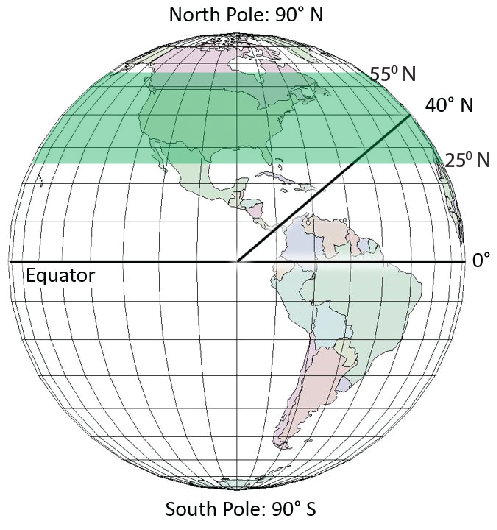

R = 6371;               % earth radius; km
R = R*1e3;              % ; m

The following integration could be done to figure out the area

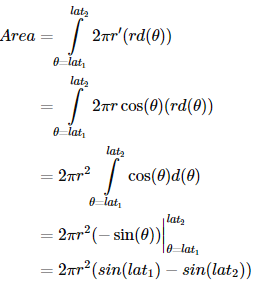

Now, we have the following

L1 = 55;                % 25d N lattitude
L2 = 25;                % 55d N lattitude
L1 = deg2rad(L1);       % radian conversion
L2 = deg2rad(L2);

So, the area of the fallout zone-

A = 2*pi*R^2 *(sin(L1) - sin(L2))      % area of the fallout zone; m^2

A = 1.0113e+14

A = A/1e4                   % fallout area; hectare

A = 1.0113e+10

So,  total number of Sr-90 deposited per hector of the ground-

NT_Sr_A = NT_Sr /A          % ; #/hec

NT_Sr_A = 1.4249e+14

(Ans)

## HW05-4

Given,

A_U1 = 500e-12;           % sp. activity of U-238; Ci.kg^-1
A_U1 = A_U1*37e9          % Bq/kg; #/kg.s

A_U1 = 18.5000

Now, let's 

Na = 6.022e23;           % Avogadro's number; #/mol
M_U1 = 0.238;            % molar mass of U-238; kg/mol

Now, $A=\lambda \;N$;

or, $A_{\textrm{sp}} =\lambda \;N_{\textrm{sp}}$        for specific (per mass) quantity

### **(a)**

**Disintegrationof U-238**

Let's look at the following decay chart

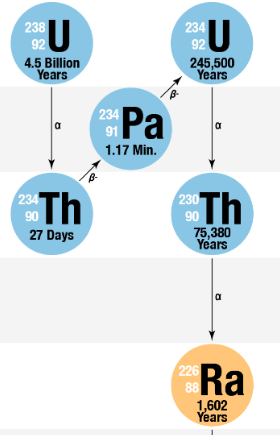

Let's find the no. of U-238 atoms in 1 kg of coal

th_U1 = 60^2*24*365* 4.5e9;     % L of U-238; sec
lam_U1 = log(2) /th_U1          % decay const of U-238; s^-1 

lam_U1 = 4.8843e-18

N_U1 = A_U1/lam_U1              % no. of U-238 atoms per kg; #/kg

N_U1 = 3.7876e+18

From the above, we can say, after 1 sec, the the U-238 per kg- converts into Th-234 produced per sec. So-

t_e = 4.5;                          % age of earth; ba
t_e = 60^2*24*365* t_e*1e9;         % ; sec

Now, we know

$N_d \left(t\right)=N_p \left(t\right)\times \left(e^{\lambda_p t\;} -1\right)$;   $d,$ for daughter; p, for parent

N_Th = N_U1*(exp(lam_U1*t_e) - 1)   % no. of Th-234; #/kg

N_Th = 3.7876e+18

**Disintegration of Th**

th_Th = 60^2*24 *27;                % HL of Th-234; sec
lam_Th = log(2)/th_Th               % decay const. of Th-234; s^-1

lam_Th = 2.9713e-07

t = 1;                              % ; sec
N_Pa = N_Th*(exp(lam_Th*t) - 1)     % no. of Pa-234 after 1s; #/kg.s

N_Pa = 1.1254e+12

**Disintegration of Pa**

th_Pa = 60*1.17;                    % HL of Pa-234; sec
lam_Pa = log(2)/th_Pa               % decay const. of Pa-234; s^-1

lam_Pa = 0.0099

N_U2 = N_Pa*(exp(lam_Pa*t) - 1)     % no. of U-234 after 1s; #/kg.s

N_U2 = 1.1167e+10

**Disintegration of U-234**

th_U2 = 60^2*24*365*2.455e5;        % HL of U-234; sec
lam_U2 = log(2)/th_U2               % decay const. of U-234; s^-1

lam_U2 = 8.9530e-14

N_Th2 = N_U2*(exp(lam_U2*t) - 1)    % no. of Th-230 after 1s; #/kg.s

N_Th2 = 9.9929e-04

**Disintegration of Th-230**

th_Th2 = 60^2*24*365*7.538e4;       % HL of Th-230; sec
lam_Th2 = log(2)/th_Th2             % decay const. of Th-230; s^-1

lam_Th2 = 2.9158e-13

N_Ra = N_Th2*(exp(lam_Th2*t) - 1)   % no. of Ra-226 after 1s; #/kg.s

N_Ra = 2.9134e-16

So, this N_Ra quantity represents the conentration of Ra-226 in coals. Let's transfer it to pCi/kg unit

N_Ra = N_Ra /37e9           % Ci/kg

N_Ra = 7.8740e-27

N_Ra = N_Ra*1e12            % pCi/kg

N_Ra = 7.8740e-15

(Ans)

**(b)**

As we found

N_Ra = N_Ra*1e-12*37e9      % Bq/kg, #/kg.s

N_Ra = 2.9134e-16

Now, we know-

M_Ra = 226;                 % molar mass of Ra-226; g/mol

Here, $M_{\textrm{sp}} =\frac{N_{\textrm{sp}} }{N_a }M$

$M_{\textrm{sp}} =$ mass(g) per mass(g/kg); $N_{\textrm{sp}} =$ no. per mass(# /kg); $M=$ molar mass (g/mol); $N_a =$Avogadro's (# /mol)

Thence,

M_sp_Ra = N_Ra/Na *M_Ra         % density of Ra-226; g/kg

M_sp_Ra = 1.0934e-37

M_sp_Ra = M_sp_Ra *1e3          % density of Ra-226; g/Mt

M_sp_Ra = 1.0934e-34

(Ans)

## HW05-5

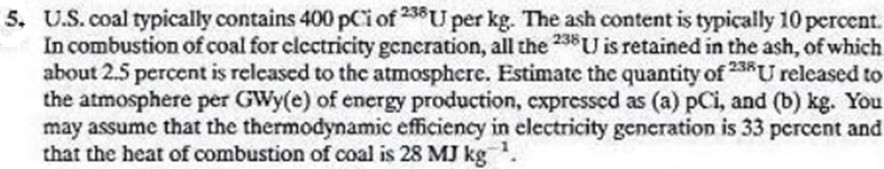

Given,

A = 400*1e-12;                  % specific activity; Ci/kg
A = 400*37e9                    % Bq/kg; #/kg.s  

A = 1.4800e+13

Now, we know

th_U = 60^2*24*365*4.5e9        % half life of U-238.; s

th_U = 1.4191e+17

lam_U = log(2)/th_U             % decay const.; s^-1

lam_U = 4.8843e-18

Then, we can deduce

N_U = A/lam_U                   % no. of U-238 atoms per kg; #/kg

N_U = 3.0301e+30

As it is said that, the ash typically contains 10% of the coal. And, all U-238 is retained by ash, so-

a_p = 0.1;              % ash percentage
N_Ua = N_U/a_p          % no. of U-238 per kg of ash; #/kg

N_Ua = 3.0301e+31

Now, we know,

m_c = 3e9;              % mass of coal burnt per GWy energy; kg/GWy

then-

m_a = m_c *a_p;         % mass of ash produced; kg/GWy

So, we have-

N_Ua2 = N_Ua *m_a       % no. of U-238 produced to generate 1 GWy energy; #/GWy

N_Ua2 = 9.0903e+39

Also given,

ar_p = 0.025;           % fraction of ash that becomes airborne
N_Uar = N_Ua2 *ar_p     % no. of U-238, airborne, @1 GWy energy; #/GWy

N_Uar = 2.2726e+38

**(a)**

Now, to express it in pCi, we have to find activity

A_Uar = N_Uar*lam_U         % Bq/GWy

A_Uar = 1.1100e+21

A_Uar = A_Uar/37e9*1e12     % pCi/GWy

A_Uar = 3.0000e+22

(Ans)

**(b)**

M_U = 0.238;                % molar mass or U-238; kg/mol
Na = 6.02e23;               % Avogadro's const.; #/mol

Here, we have


$$M_{\mathrm{GWy}} =\frac{N_{\mathrm{GWy}} }{N_a }M$$


M_Uar = N_Uar/Na *M_U       % mass of U--238, airborne, @ GWy energy; kg/GWy

M_Uar = 8.9846e+13

(Ans)